# **10 Minute Recording Short Data**

clear all close all
load('MAT/Short_Final_Swapped.bag.mat')
t0 = 1/cast(FSampling, 'double');

### Statistics

  AngleMean = [mean(Theta_x), mean(Theta_y),mean(Theta_z)]

AngleMean =    -0.0249   -0.0209   -0.0575


  RateMean  = [mean(Omega_x), mean(Omega_y),mean(Omega_z)]

RateMean =    -0.4162   -0.3836    0.5719


  AcclMean  = [mean(Alpha_x), mean(Alpha_y),mean(Alpha_z)]

AcclMean =    -0.2030    0.2414   -9.6765


  MagMean   = [mean(Mag_x), mean(Mag_y),mean(Mag_z)]

MagMean =    -0.0663    0.0253    0.1628



  AngleStdev = [std(Theta_x), std(Theta_y),std(Theta_z)]

AngleStdev = 	1.0e+-3 *

    0.1115    0.0987    0.5517


  RateStdev  = [std(Omega_x), std(Omega_y),std(Omega_z)]

RateStdev =     0.0095    0.0090    0.0060


  AcclStdev  = [std(Alpha_x), std(Alpha_y),std(Alpha_z)]

AcclStdev =     0.0122    0.0116    0.0168


  MagStdev   = [std(Mag_x), std(Mag_y),std(Mag_z)]

MagStdev =     0.0008    0.0025    0.0028


### Plots

#### Angle Variations

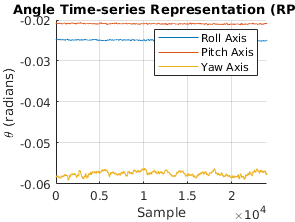


  figure("Name","Semilog angular variations")
  hold on
  semilogx(Theta_x)
  semilogx(Theta_y)
  semilogx(Theta_z)
  title('Angle Time-series Representation (RPY)')
  ylabel('\theta (radians)');
  xlabel('Sample')
  grid on
  legend('Roll Axis', 'Pitch Axis', 'Yaw Axis')

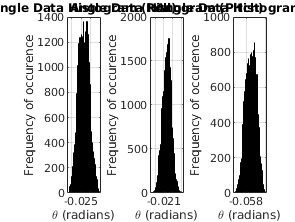


  figure("Name","Histogram of angular variations")
  subplot(1,3,1)
  histogram(Theta_x)
  title('Angle Data Histogram (Roll)')
  xlabel('\theta (radians)');
  ylabel('Frequency of occurence')
  grid on

  subplot(1,3,2)
  histogram(Theta_y)
  title('Angle Data Histogram (Pitch)')
   xlabel('\theta (radians)');
  ylabel('Frequency of occurence')
  grid on

  subplot(1,3,3)
  histogram(Theta_z)
  title('Angle Data Histogram (Yaw)')
  xlabel('\theta (radians)');
  ylabel('Frequency of occurence')
  grid on

#### Rate Variations

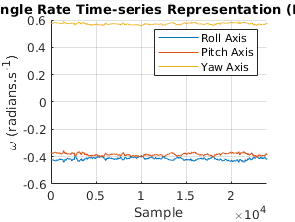


  figure("Name","Semilog angular rate variations")
  hold on
  semilogx(Omega_x)
  semilogx(Omega_y)
  semilogx(Omega_z)
  title('Angle Rate Time-series Representation (RPY)')
  ylabel('\omega (radians.s^{-1})');
  xlabel('Sample')
  grid on
  legend('Roll Axis', 'Pitch Axis', 'Yaw Axis')

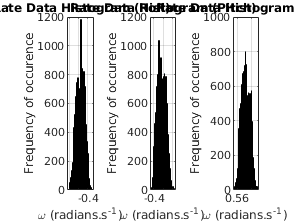



  figure("Name","Histogram of angular rate variations")
  subplot(1,3,1)
  histogram(Omega_x)
  title('Rate Data Histogram (Roll)')
  xlabel('\omega (radians.s^{-1})');
  ylabel('Frequency of occurence')
  grid on

  subplot(1,3,2)
  histogram(Omega_y)
  title('Rate Data Histogram (Pitch)')
  xlabel('\omega (radians.s^{-1})');
  ylabel('Frequency of occurence')
  grid on

  subplot(1,3,3)
  histogram(Omega_z)
  title('Rate Data Histogram (Yaw)')
  xlabel('\omega (radians.s^{-1})');
  ylabel('Frequency of occurence')
  grid on

#### Accelerometer Variations

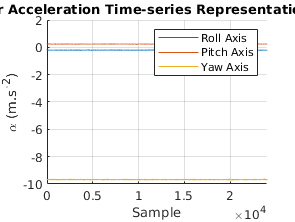


  figure("Name","Semilog Accelerometer variations")
  hold on
  semilogx(Alpha_x)
  semilogx(Alpha_y)
  semilogx(Alpha_z)
  title('Linear Acceleration Time-series Representation (RPY)')
  ylabel('\alpha (m.s^{-2})');
  xlabel('Sample')
  grid on
  legend('Roll Axis', 'Pitch Axis', 'Yaw Axis')

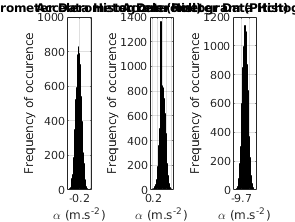


 
 figure("Name","Histogram of linear acceleration rate variations")
  subplot(1,3,1)
  histogram(Alpha_x)
  title('Accelerometer Data Histogram (Roll)')
  xlabel('\alpha (m.s^{-2})');
  ylabel('Frequency of occurence')
  grid on

  subplot(1,3,2)
  histogram(Alpha_y)
  title('Accelerometer Data Histogram (Pitch)')
  xlabel('\alpha (m.s^{-2})');
  ylabel('Frequency of occurence')
  grid on

  subplot(1,3,3)
  histogram(Alpha_z)
  title('Accelerometer Data Histogram (Yaw)')
  xlabel('\alpha (m.s^{-2})');
  ylabel('Frequency of occurence')
  grid on

#### Magnetometer Variations

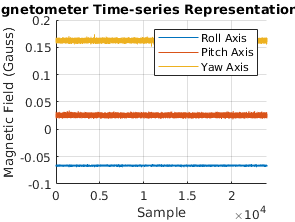


  figure("Name","Semilog angular variations")
  hold on
  semilogx(Mag_x)
  semilogx(Mag_y)
  semilogx(Mag_z)
  title('Magnetometer Time-series Representation (RPY)')
  ylabel('Magnetic Field (Gauss)');
  xlabel('Sample')
  grid on
  legend('Roll Axis', 'Pitch Axis', 'Yaw Axis')

# **5 Hour Recording Data (GYRO ALLAN VARIANCE)**

%% Allan Variance Calculation
% The Allan variance is calculated as follows:
% 
% Log _L_ stationary gyroscope samples with a sample period $\tau_{0}$. Let 
% $\Omega$ be the logged samples. 

% Load logged data from three axes of a three-axis gyroscope. This recording
% was done over a 7 hour period with a 40 Hz sampling rate. 

clear all close all

% load('MAT/Long_Final.bag.mat')
load('MAT/Long_Final_Rates.mat')
t0 = 1/cast(FSampling, 'double');

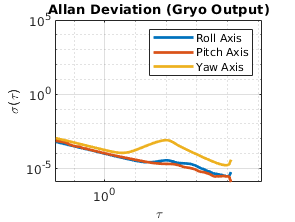


% 
% For each sample, calculate the output angle $\theta$:
%
% $$\theta(t) = \int^{t}\Omega(t')dt'$$
%
% For discrete samples, the cumulative sum multiplied by $\tau_{0}$ can be
% used.
Omega_x = x;
Omega_y = y;
Omega_z = z;
omega = [Omega_x', Omega_y', Omega_z'];
theta = cumsum(omega, 1)*t0;

%%
%
% Next, calculate the Allan variance:
%
% $$\sigma^2(\tau) =
% \frac{1}{2\tau^2}<(\theta_{k+2m}-2\theta_{k+m}+\theta_{k})^2>$$
%
% where $\tau = m\tau_{0}$ and $<>$ is the ensemble average. 
%
% The ensemble average can be expanded to:
% 
% $$\sigma^2(\tau) =
% \frac{1}{2\tau^2(L-2m)}\sum_{k=1}^{L-2m}(\theta_{k+2m} - 2\theta_{k+m}
% + \theta_{k})^2$$

maxNumM = 100;
L = size(theta, 1);
maxM = 2.^floor(log2(L/2)); 
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

figure("Name","ALLANVAR FOR GYRO OUTPUT OF VN-100S")
%Loop through XYZ Axes rate measurements and calculate AVAR for each
avar = zeros(numel(m), 3);
for ax_counter =1:3
   for i = 1:numel(m)
        mi = m(i);
        avar(i,ax_counter) = sum( ...
            (theta(1+2*mi:L,ax_counter) - 2*theta(1+mi:L-mi,ax_counter) + theta(1:L-2*mi,ax_counter)).^2, 1);
    end
    avar(:,ax_counter) = avar(:,ax_counter) ./ (2*tau.^2 .* (L - 2*m));
    %%
    %
    % Finally, the Allan deviation $\sigma(t) = \sqrt{\sigma^2(t)}$ is used to 
    % determine the gyroscope noise parameters. 
    adev(:,ax_counter) = sqrt(avar(:,ax_counter));
 
  
%     [avarFromFunc(:,ax_counter), tauFromFunc(:,ax_counter)] = allanvar(omega(:,ax_counter), m, FSampling); %#ok<*SAGROW> 
%     adevFromFunc(:,ax_counter) = sqrt(avarFromFunc(:,ax_counter));
end
    
   loglog(tau, adev(:,1), ...
        tau, adev(:,2), ...
        tau, adev(:,3), 'LineWidth',2);
    title('Allan Deviation (Gryo Output)')
    xlabel('\tau');
    ylabel('\sigma(\tau)')
    grid on
    axis equal


%     loglog(tauFromFunc(:,1), adevFromFunc(:,1), ...
%         tauFromFunc(:,2), adevFromFunc(:,2), ...
%         tauFromFunc(:,3), adevFromFunc(:,3));
%     axis equal
%     title('Allan Deviations')
%     xlabel('\tau')
%     ylabel('\sigma(\tau)')
%     grid on

    legend('Roll Axis', 'Pitch Axis', 'Yaw Axis')

clearvars -except adev tau m

## Angle Random Walk

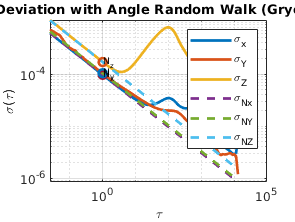

slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
% dlogadevX = diff(logadev(:,1)) ./ diff(logtau);
% dlogadevY = diff(logadev(:,2)) ./ diff(logtau);
% dlogadevZ = diff(logadev(:,3)) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
for ax = 1:3
    b(ax) = logadev(i(ax),ax) - slope*logtau(i(ax));
    logN(ax) = slope*log(1) + b(ax);
    N(ax) = 10^logN(ax);
end

% Determine the angle random walk coefficient from the line.


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);

figure("Name","Angle random walk")
loglog(tau, adev,tau, lineN, '--', tauN, N, 'o', 'LineWidth',2);
title('Allan Deviation with Angle Random Walk (Gryo Output)')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma_{x}', '\sigma_{Y}', '\sigma_{Z}','\sigma_{Nx}', '\sigma_{NY}', '\sigma_{NZ}')
text(tauN, N(1), 'N_{x}','FontSize',7)
text(tauN, N(2), 'N_{y}','FontSize',7)
text(tauN, N(3), 'N_{z}','FontSize',7)
grid on

## Rate Random Walk

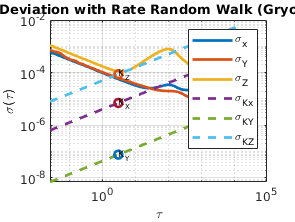

slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));



for ax = 1:3
    b(ax) = logadev(i(ax),ax) - slope*logtau(i(ax));
    logK(ax) = slope*log10(3) + b(ax);
    K(ax) = 10^logK(ax);
end



% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);
figure("Name","Rate random walk")
loglog(tau, adev, tau, lineK, '--', tauK, K, 'o', 'LineWidth',2)
title('Allan Deviation with Rate Random Walk (Gryo Output)')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma_{x}', '\sigma_{Y}', '\sigma_{Z}','\sigma_{Kx}', '\sigma_{KY}', '\sigma_{KZ}')
text(tauK, K(1), 'K_{X}','FontSize',7)
text(tauK, K(2), 'K_{Y}','FontSize',7)
text(tauK, K(3), 'K_{Z}','FontSize',7)
grid on

## Bias Instability

slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

for ax =1:length(i)
    b(ax) = logadev(i(ax),ax) - slope*logtau(i(ax));
    scfB = sqrt(2*log(2)/pi);
    logB(ax) = b(ax) - log10(scfB);
    B(ax) = 10^logB(ax)
end

B = 	1.0e+-3 *

    0.0333    0.0301    0.1663


B = 	1.0e+-3 *

    0.0333    0.0301    0.1663


B = 	1.0e+-3 *

    0.0333    0.0301    0.1663


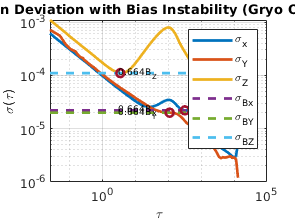



% Plot the results.
tauB = tau(i);
for x = 1:length(b)
lineB(:,x) = B(x)* scfB * ones(size(tau));
end
figure("Name","Gyro Bias instability")
loglog(tau, adev, tau, lineB, '--', tauB, scfB*B, 'o', 'LineWidth',2)
title('Allan Deviation with Bias Instability (Gryo Output)')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma_{x}', '\sigma_{Y}', '\sigma_{Z}','\sigma_{Bx}', '\sigma_{BY}', '\sigma_{BZ}')
grid on

text(tauK, scfB*B(1), '0.664B_{X}', 'FontSize',7)
text(tauK, scfB*B(2), '0.664B_{Y}','FontSize',7)
text(tauK, scfB*B(3), '0.664B_{Z}','FontSize',7)

grid on


%% 
%
% Now that all the noise parameters have been calculated, plot the Allan
% deviation with all of the lines used for quantifying the parameters.
tauParams = [tauN, tauK, tauB(1); tauN, tauK, tauB(2);tauN, tauK, tauB(3);];
params = [N(1), K(1), scfB*B(1); N(2), K(2), scfB*B(2); N(3), K(3), scfB*B(3)];

Axes = ["Roll", "Pitch", "Yaw"]

Axes = 1×3 string array
    "Roll"    "Pitch"    "Yaw"

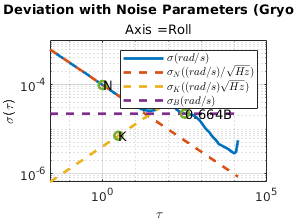

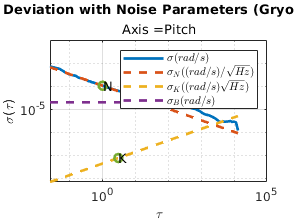

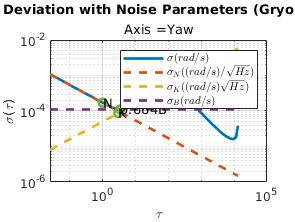

for i =1:3
    figure("Name","Allan Deviation with noise Params")
%     loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
%         tauParams, params, 'o')
  loglog(tau, adev(:,i), tau, [lineN(:,i), lineK(:,i), lineB(:,i)], '--', ...
        tauParams(i,:), params(i,:), 'o', 'LineWidth',2)
    title('Allan Deviation with Noise Parameters (Gryo Output)','Axis ='+string(Axes(i)))
    xlabel('\tau')
    ylabel('\sigma(\tau)')
    legend('$\sigma (rad/s)$', '$\sigma_N ((rad/s)/\sqrt{Hz})$', ...
        '$\sigma_K ((rad/s)\sqrt{Hz})$', '$\sigma_B (rad/s)$', 'Interpreter', 'latex')
    text(tauParams(i,:), params(i,:), {'N', 'K', '0.664B'})
    grid on
    
end

# **7 Hour Recording Data (Accelerometer ALLAN VARIANCE)**

clear all close all


load('MAT/5_hour_imu.mat')
t0 = 1/40

t0 = 0.0250

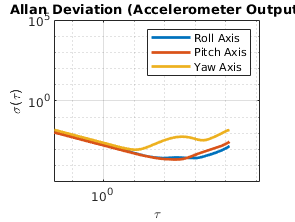


% 
% For each sample, calculate the output angle $\theta$:
%
% $$\theta(t) = \int^{t}\Omega(t')dt'$$
%
% For discrete samples, the cumulative sum multiplied by $\tau_{0}$ can be
% used.
alpha = [lin_acc_x', lin_acc_y', lin_acc_z'];
Vel = cumsum(alpha, 1)*t0;

%%
%
% Next, calculate the Allan variance:
%
% $$\sigma^2(\tau) =
% \frac{1}{2\tau^2}<(\theta_{k+2m}-2\theta_{k+m}+\theta_{k})^2>$$
%
% where $\tau = m\tau_{0}$ and $<>$ is the ensemble average. 
%
% The ensemble average can be expanded to:
% 
% $$\sigma^2(\tau) =
% \frac{1}{2\tau^2(L-2m)}\sum_{k=1}^{L-2m}(\theta_{k+2m} - 2\theta_{k+m}
% + \theta_{k})^2$$

maxNumM = 100;
L = size(Vel, 1);
maxM = 2.^floor(log2(L/2)); 
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

figure("Name","ALLANVAR FOR GYRO OUTPUT OF VN-100S")
%Loop through XYZ Axes rate measurements and calculate AVAR for each
avar = zeros(numel(m), 3);
for ax_counter =1:3
   for i = 1:numel(m)
        mi = m(i);
        avar(i,ax_counter) = sum( ...
            (Vel(1+2*mi:L,ax_counter) - 2*Vel(1+mi:L-mi,ax_counter) + Vel(1:L-2*mi,ax_counter)).^2, 1);
    end
    avar(:,ax_counter) = avar(:,ax_counter) ./ (2*tau.^2 .* (L - 2*m));
    %%
    %
    % Finally, the Allan deviation $\sigma(t) = \sqrt{\sigma^2(t)}$ is used to 
    % determine the gyroscope noise parameters. 
    adev(:,ax_counter) = sqrt(avar(:,ax_counter));
 
  
%     [avarFromFunc(:,ax_counter), tauFromFunc(:,ax_counter)] = allanvar(omega(:,ax_counter), m, FSampling); %#ok<*SAGROW> 
%     adevFromFunc(:,ax_counter) = sqrt(avarFromFunc(:,ax_counter));
end
    
   loglog(tau, adev(:,1), ...
        tau, adev(:,2), ...
        tau, adev(:,3), 'LineWidth',2);
    title('Allan Deviation (Accelerometer Output)')
    xlabel('\tau');
    ylabel('\sigma(\tau)')
    grid on
    axis equal


%     loglog(tauFromFunc(:,1), adevFromFunc(:,1), ...
%         tauFromFunc(:,2), adevFromFunc(:,2), ...
%         tauFromFunc(:,3), adevFromFunc(:,3));
%     axis equal
%     title('Allan Deviations')
%     xlabel('\tau')
%     ylabel('\sigma(\tau)')
%     grid on

    legend('Roll Axis', 'Pitch Axis', 'Yaw Axis')

clearvars -except adev tau m

## Angle Random Walk

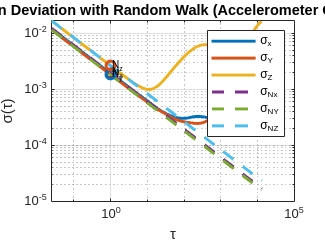

slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
% dlogadevX = diff(logadev(:,1)) ./ diff(logtau);
% dlogadevY = diff(logadev(:,2)) ./ diff(logtau);
% dlogadevZ = diff(logadev(:,3)) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
for ax = 1:3
    b(ax) = logadev(i(ax),ax) - slope*logtau(i(ax));
    logN(ax) = slope*log(1) + b(ax);
    N(ax) = 10^logN(ax);
end

% Determine the angle random walk coefficient from the line.


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);

figure("Name","Angle random walk")
loglog(tau, adev,tau, lineN, '--', tauN, N, 'o', 'LineWidth',2);
title('Allan Deviation with Random Walk (Accelerometer Output)')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma_{x}', '\sigma_{Y}', '\sigma_{Z}','\sigma_{Nx}', '\sigma_{NY}', '\sigma_{NZ}')
text(tauN, N(1), 'N_{x}','FontSize',7)
text(tauN, N(2), 'N_{y}','FontSize',7)
text(tauN, N(3), 'N_{z}','FontSize',7)
grid on

## Rate Random Walk

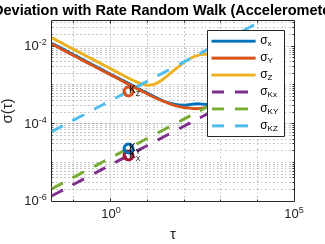

slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));



for ax = 1:3
    b(ax) = logadev(i(ax),ax) - slope*logtau(i(ax));
    logK(ax) = slope*log10(3) + b(ax);
    K(ax) = 10^logK(ax);
end



% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);
figure("Name","Rate random walk")
loglog(tau, adev, tau, lineK, '--', tauK, K, 'o', 'LineWidth',2)
title('Allan Deviation with Rate Random Walk (Accelerometer Output)')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma_{x}', '\sigma_{Y}', '\sigma_{Z}','\sigma_{Kx}', '\sigma_{KY}', '\sigma_{KZ}')
text(tauK, K(1), 'K_{X}','FontSize',7)
text(tauK, K(2), 'K_{Y}','FontSize',7)
text(tauK, K(3), 'K_{Z}','FontSize',7)
grid on

## Bias Instability

slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

for ax =1:length(i)
    b(ax) = logadev(i(ax),ax) - slope*logtau(i(ax));
    scfB = sqrt(2*log(2)/pi);
    logB(ax) = b(ax) - log10(scfB);
    B(ax) = 10^logB(ax)
end

B = 4.5421e-04

B = 	1.0e+-3 *

    0.4542    0.3681


B =     0.0005    0.0004    0.0015


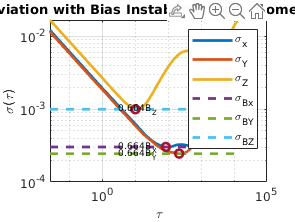



% Plot the results.
tauB = tau(i);
for x = 1:length(b)
lineB(:,x) = B(x)* scfB * ones(size(tau));
end
figure("Name","Gyro Bias instability")
loglog(tau, adev, tau, lineB, '--', tauB, scfB*B, 'o', 'LineWidth',2)
title('Allan Deviation with Bias Instability (Accelerometer Output)')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma_{x}', '\sigma_{Y}', '\sigma_{Z}','\sigma_{Bx}', '\sigma_{BY}', '\sigma_{BZ}')
grid on

text(tauK, scfB*B(1), '0.664B_{X}', 'FontSize',7)
text(tauK, scfB*B(2), '0.664B_{Y}','FontSize',7)
text(tauK, scfB*B(3), '0.664B_{Z}','FontSize',7)

grid on


%% 
%
% Now that all the noise parameters have been calculated, plot the Allan
% deviation with all of the lines used for quantifying the parameters.
tauParams = [tauN, tauK, tauB(1); tauN, tauK, tauB(2);tauN, tauK, tauB(3);];
params = [N(1), K(1), scfB*B(1); N(2), K(2), scfB*B(2); N(3), K(3), scfB*B(3)];

Axes = ["Roll", "Pitch", "Yaw"]

Axes = 1×3 string array
    "Roll"    "Pitch"    "Yaw"

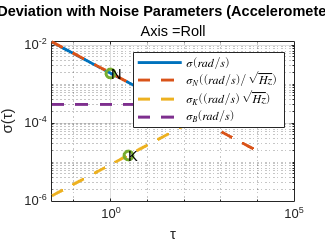

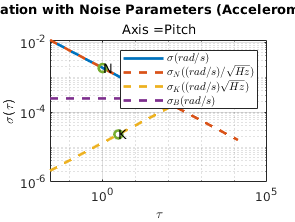

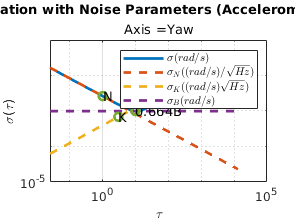

for i =1:3
    figure("Name","Allan Deviation with noise Params")
%     loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
%         tauParams, params, 'o')
  loglog(tau, adev(:,i), tau, [lineN(:,i), lineK(:,i), lineB(:,i)], '--', ...
        tauParams(i,:), params(i,:), 'o', 'LineWidth',2)
    title('Allan Deviation with Noise Parameters (Accelerometer Output)','Axis ='+string(Axes(i)))
    xlabel('\tau')
    ylabel('\sigma(\tau)')
    legend('$\sigma (rad/s)$', '$\sigma_N ((rad/s)/\sqrt{Hz})$', ...
        '$\sigma_K ((rad/s)\sqrt{Hz})$', '$\sigma_B (rad/s)$', 'Interpreter', 'latex')
    text(tauParams(i,:), params(i,:), {'N', 'K', '0.664B'})
    grid on
    
end